# Regression for finding binding energies

Now that we know how to estimate the mean integrated fluorescence intensity for each of our strains, with error bars, we will move on to do regression to estimate the binding energy of the LacI repressor to the operator.  As we derived, the fold change in gene expression may be written as


$$\text{fold change} = 1/(1 + 2R\mathrm{e}^{-\beta E_\mathrm{rd}}/N_\mathrm{NS}),$$


where $R$ is the number of repressors in a cell, $N_\mathrm{NS} \approx 5\times 10^6$ is the number of non-specific binding sites for the repressors, and $\beta E_\mathrm{rd}$ is the binding energy in units of the thermal energy $k_BT$.  For the purposes of regression, we define


$$a \equiv 2\mathrm{e}^{-\beta E_\mathrm{rd}}/N_\mathrm{NS}$$


as our single regression parameter such that


$$\text{fold change} = (1+aR)^{-1}.$$


It is useful to plot this, just so we know what the data should look like according to the statistical mechanical model for gene expression regulation.

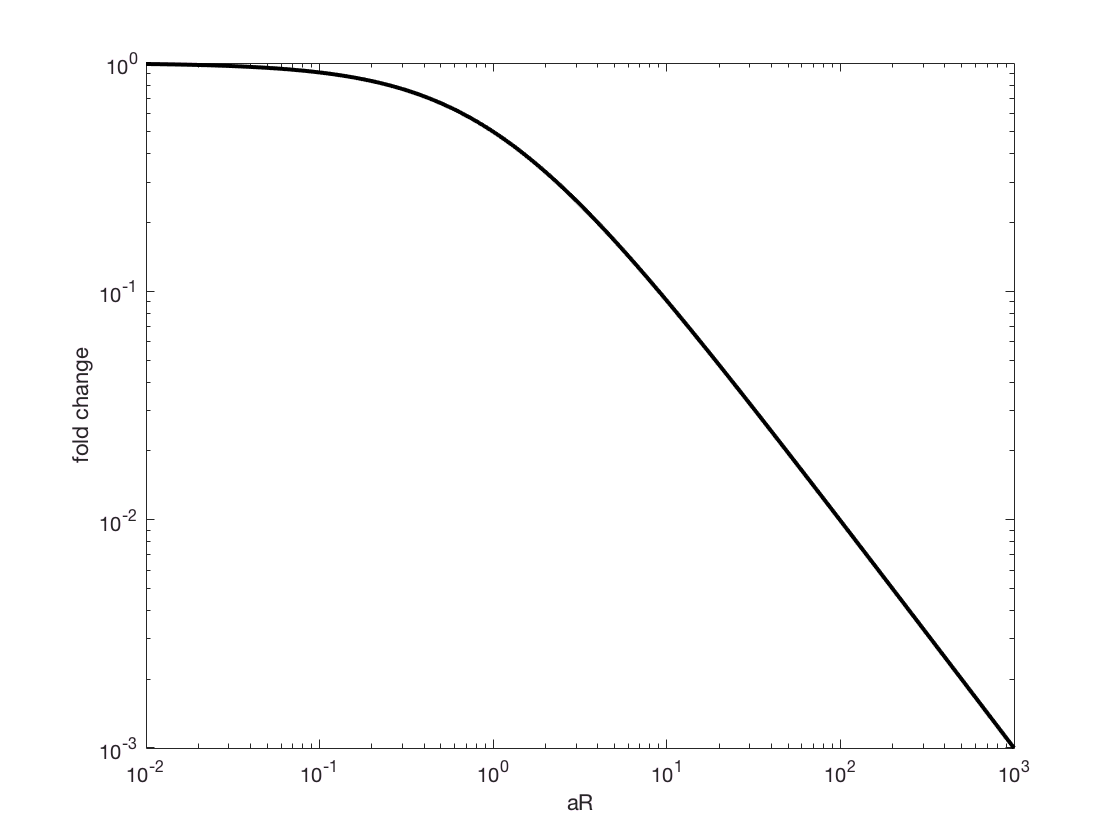

aR = logspace(-2, 3, 200);
loglog(aR, 1 ./ (1 + aR), 'k-', 'linewidth', 2);
xlabel('aR');
ylabel('fold change');

So, for large repressor copy numbers, we expect log-linearity of the fold change with a slope of $-1$ with an asymptote to unity for small repressor copy numbers.

## Loading in the data sets

In order to do the regression, we need to know how many repressors each strain has.  Garcia and Phillips (*PNAS*, 2011) measured this using quantitative immunoblots.  They got

- WT: 11 ± 2

- RBS1147: 30 ± 10

- RBS446: 62 ± 15

- RBS1027: 130 ± 20

- RBS1: 610 ± 80

Obviously, the Delta strain has zero repressors.   The error bars on each of these is one standard deviation.  For a complete analysis, we could take into account the errors in the measured repressor copy numbers.  This would result in a more complicated statistical model, which we will not attempt here.  Instead, we will take the average repressor copy number to be that of each cell of a given strain and assume that the error in repressor copy number is manifest in the errors we get in measurement of the fluorescence intensity.  I.e., the error bars we compute in the fluroescence intensity contain all sources of error, including fluctuations in repressor copy number.

It is useful to keep a list of the strain names and copy numbers.

strains = {'Delta', 'WT', 'RBS1147', 'RBS446', 'RBS1027', 'RBS1'};
R = [0, 11, 30, 62, 130, 610]';

We will now load in the data sets and compute the mean and standard error of the mean of integrated intensities for each of the strains.  Here, we are just parsing the CSV files generated from our dry run images.

cd ~/git/mbl_physiology_matlab/gene_expression;
meanIntensities = zeros(length(strains), 1);
semIntensities = zeros(length(strains), 1);
for i = 1:length(strains)
    intInt = csvread(sprintf('%s_dryrun_intensities.csv', strains{i}));
    meanIntensities(i) = mean(intInt);
    semIntensities(i) = std(intInt) / sqrt(length(intInt));
end %for

## Exploring the results and computing fold change

It is often useful to do some **exploratory data analysis** before proceding with more quantitative analysis.  This typically involves plotting and other invstigation of the data to make sure everything makes sense.

Actually, I pause now to make an important point.  Prior to *any* analysis, you should do **data validation**.  This means that you should inspect the data to make sure there are no inherent issues with it.  In imaging data, this means checking for dropped frames, checking all the metadata, etc.  You should automate this using **unit tests**, but these are programming/data handling best practices that we do not have time to cover now.  But, please, in your own work, validate your data to make sure it is what you think it is.

Back to exploratory data analysis. Let's plot the integrated intensities with error bars representing that 95% confidence interval.

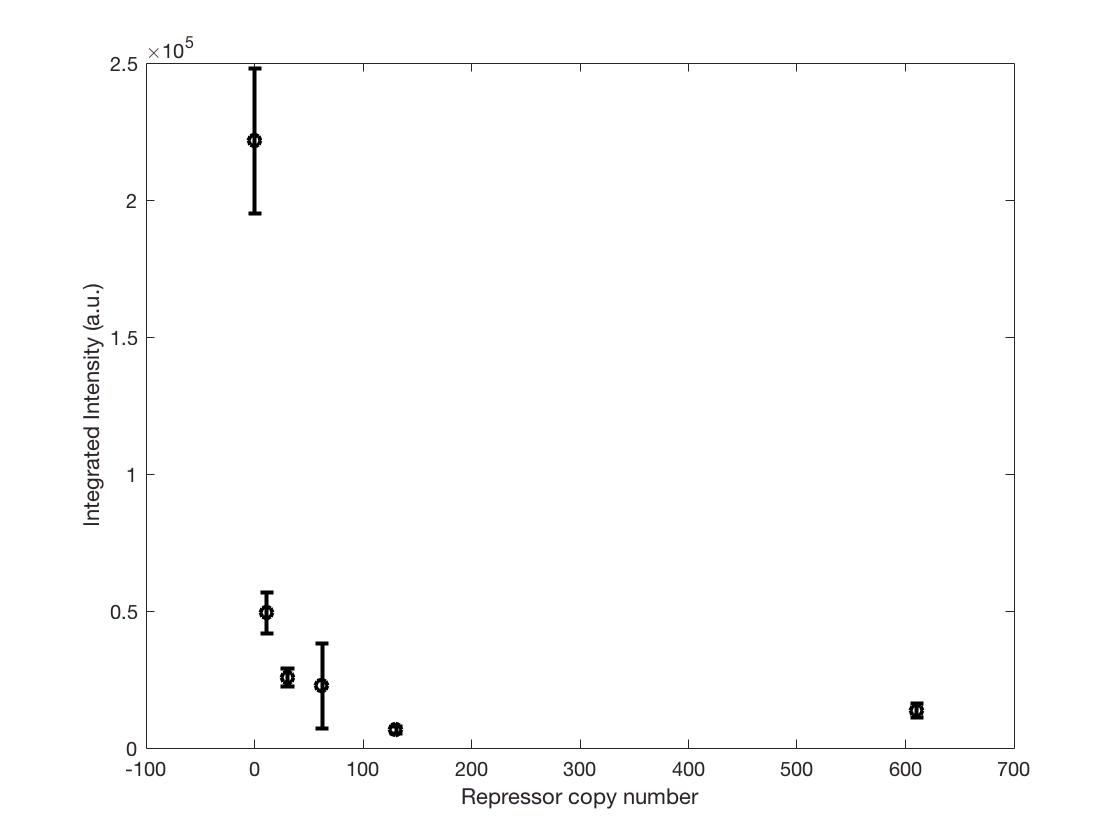

figure();
errorbar(R, meanIntensities, 2*semIntensities, 'ko', 'linewidth', 2);
xlabel('Repressor copy number');
ylabel('Integrated Intensity (a.u.)');

Eyeballing it, it appears as though wild type has a fold change of about 0.25, which means we should be close to the log-linear regime, as per our plot of the theoretical fold change curve.

This is fine and good, but we would like to plot the fold change, since, after all, that is what our model describes.  The problem is what to do with the error.  This is actually a difficult question, and I will side-step it for now.  Instead, I will state an approximate result.  Say we have to Gaussian distributed random variables, $x$ and $y$ with respective mean, variance pairs $\mu_x, \sigma_x^2$ and $\mu_y, \sigma_y^2$.  What is the mean and variance of $z=x/y$?  The mean is $\mu_z = \mu_x/\mu_y$ and the variance is approximately $\sigma_z^2 \approx \mu_z^2(\sigma_x^2/\mu_x^2 + \sigma_y^2/\mu_y^2)$.  So, we will compute the fold change and its error bar using these formulae, where $z$ is the fold change, $x$ is the integrated intensity of a given strain, and $y$ is the integrated intensity of the unregulated (Delta) strain.

foldChange = meanIntensities(2:end) / meanIntensities(1);
semFoldChange = sqrt(foldChange.^2 .* ...
        (semIntensities(2:end).^2 ./ meanIntensities(2:end).^2 + ...
         semIntensities(1)^2 / meanIntensities(1)^2));

Let's plot the fold change with 95% confidence interval error bars.

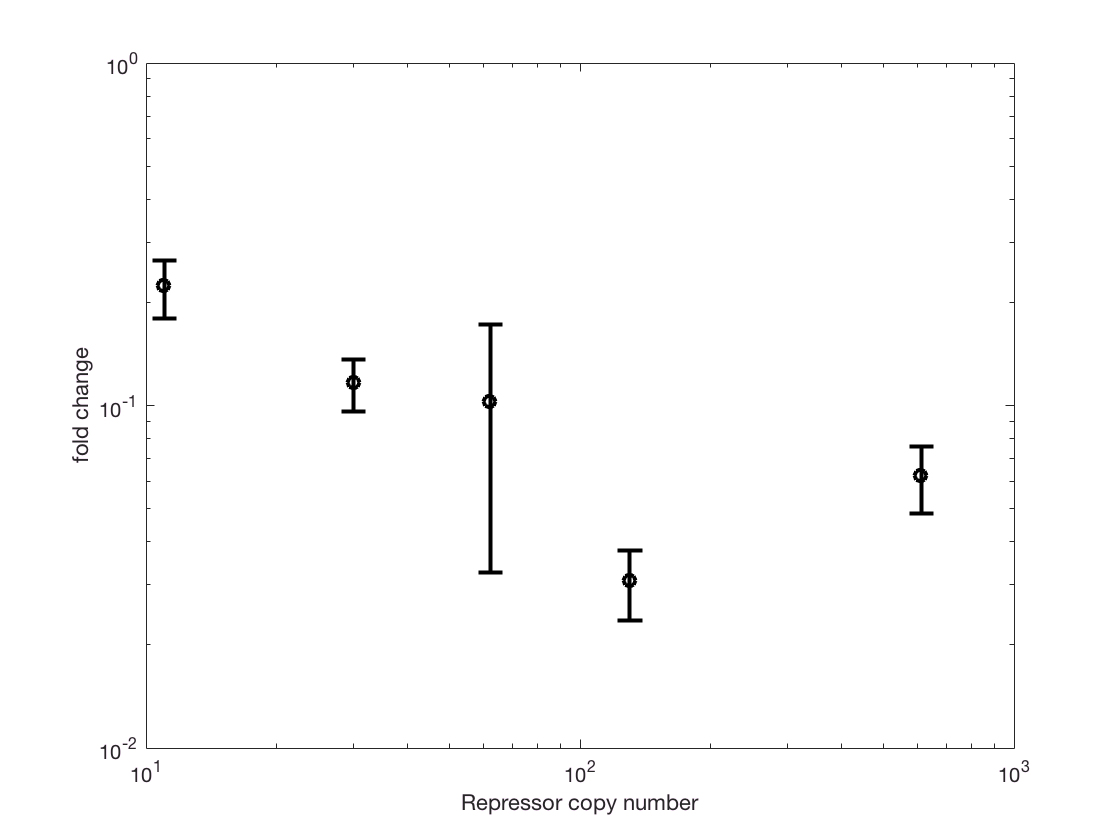

figure();
errorbar(R(2:end), foldChange, 2*semFoldChange, 'ko', 'linewidth', 2);
ax = gca();
set(ax,'XScale', 'log', 'YScale', 'log')
xlabel('Repressor copy number');
ylabel('fold change');

The first four points indeed seem close to line along a line on a log-log plot, as we expect.  The last data point, for high repressor copy numbers, is high.  Is this an outlier?  It depends on what we mean by outlier.  We probably have greater noise at low expression levels.  Indeed, if we were to repeat the measurement (as opposed to the *replicates* we have in the dry run data), we might measure a lower fold change.  It is also possible that we are approaching the limit of detection.

We can even eyeball the data and come up with our best guess for $a$.  The wild type has about 10 copies of the repressor, and has a fold change of about 1/4.  For a fold change of 1/4, $aR = 3$, so we would guess that $a\approx 1/3$.

Having explored the data, we know that we are in the log-linear regime of the fold change curve and that there may be an issue with the measurement at high repressor copy number.  We even have a decent guess for what the parameter $a$ is!  You can learn a lot just by looking and thinking about your data (and you always should!).

## Parameter estimation: the chi-square statistic

In finding the parameter $a$ that best describes the data under our model, we consider the **residuals** of the data.  A residual of a measured datum $\hat{y}_i$ and its theoretical value $y(x_i)$ is defined as


$$r_i = (\hat{y}_i - y(x_i;a)) / \sigma_i,$$


where $\sigma_i^2$ is the variance associated with the datum.  The **chi-square statistic** is the sum of the square of the residuals, or


$$\chi^2(a) = \sum_i r_i^2 = \sum_i\frac{(\hat{y}_i-y(x_i;a))^2}{\sigma_i^2}.$$


If we expect the data to be Gaussian distributed (i.e., there are no outliers), the value of $a$ that minimizes the chi-square statistic is the one that best describes the data.  Note that the larger the variance for a given datum, the less influence it has over the chi-square statistic, and therefore also over the best fit parameter value.

Let's plot the chi-square statistic for our data set as a function of $a$.  We are computing this with nested `for` loops, which is inelegant in inefficient, but is good for pedagogial purposes.

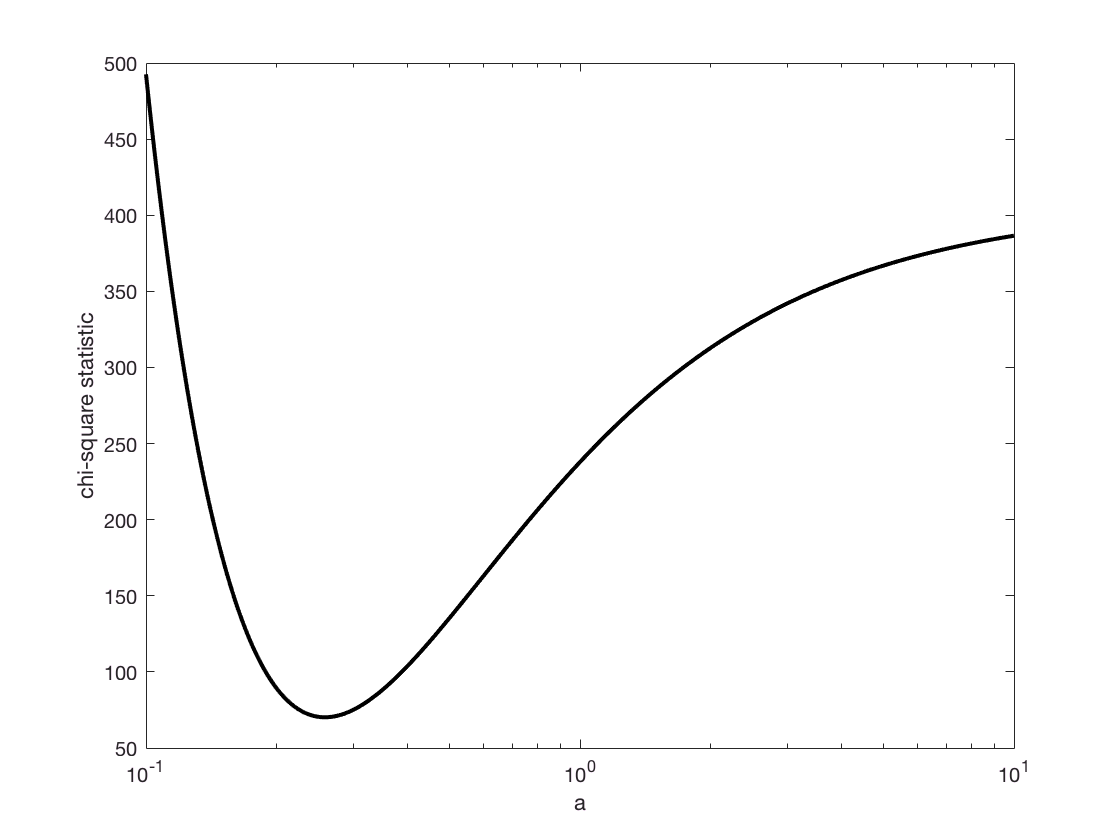

% Values of a to plot, bearing in mind that we guess a ≈ 1/3
aPlot = logspace(-1, 1, 400);

chiSquare = zeros(length(aPlot), 1);
for i = 1:length(aPlot)
    for j = 1:length(foldChange)
        yTheor = 1 / (1 + aPlot(i) * R(j+1));
        chiSquare(i) = chiSquare(i) + ...
                    ((foldChange(j) - yTheor) / semFoldChange(j))^2;
    end %for
end %for

figure();
semilogx(aPlot, chiSquare, 'k-', 'linewidth', 2);
xlabel('a');
ylabel('chi-square statistic');

Indeed, we find that the optimal value of $a$ is about 0.3, which is what we guessed in the first place.  We can find its approximate value by finding the value of $R$ for which the chi-square statistic is minimal in our plot.  We just ask Matlab where the minimun is.

[minChiSquare, minIndex] = min(chiSquare);
aBest = aPlot(minIndex);
disp(aBest);

    0.2576



So, the best fit value for $a$ is 0.26.  From this, we can compute the estimated binding energy,


$$\beta E_\mathrm{rd} = -\ln(2/aN_\mathrm{NS}).$$


betaErd = -log(2 / aBest / 5e6);
disp(betaErd);

   13.3756



So, the binding energy of the LacI repressor is about $13k_BT$, which is in the ballpark of that published in the Garcia and Phillips paper.

Let's plot our best-fit curve with our data.

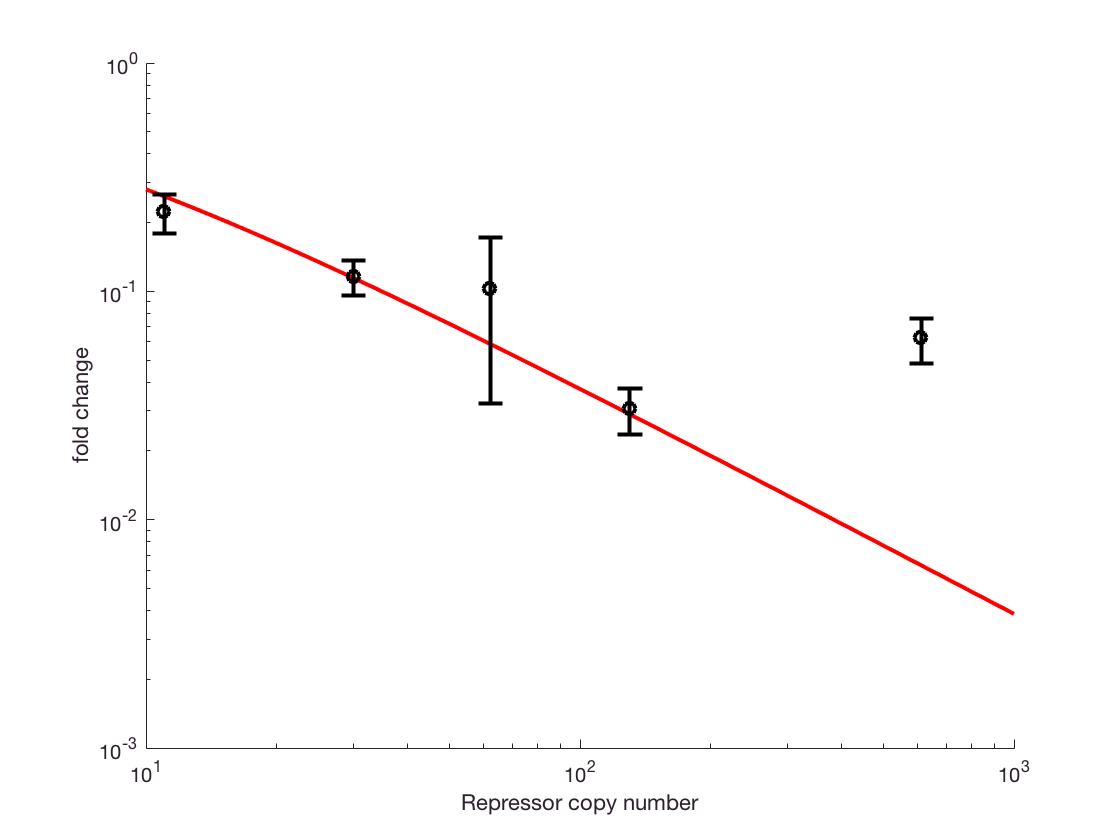

% Compute theoretical curve
RPlot = logspace(1, 3, 400);
foldChangeTheor = 1 ./ (1 + aBest * RPlot);

% Generate figure on log-log plot
figure();
hold on;
loglog(RPlot, foldChangeTheor, 'r-', 'linewidth', 2);
errorbar(R(2:end), foldChange, 2*semFoldChange, 'ko', 'linewidth', 2);
ax = gca();
set(ax,'XScale', 'log', 'YScale', 'log')
xlabel('Repressor copy number');
ylabel('fold change');

At least in terms of finding the optimal value of our parameter, the high repressor copy number data did not adversely affect the regression.

## Regression in Matlab

Our method of plotting the chi-square distribution and finding the minimum is a very inefficient way of finding the optimal parameter values.  Instead, we can use techniques of **numerial optimization** to perform the regression.  Having an efficient way to perform the regression also enables us to use bootstrapping to get confidence intervals on the fit parameters.

The problem of minimizing a chi-square statistic involved minimizing the sum of squared quantities. It therefore lends itself to the **Levenberg-Marquardt** algorithm.  The Matlab function `lsqnonlin` does just that.  (Actually, by default, is uses a trust region method, but we will not go into those details here.)

To use `lsqnonlin`, we need to define a vector-valued function that is to be squared and summed.  This function, in our case, is the residuals.  Because of the way Matlab requires specification of functions in separate M-files (do not even get me started on this), we will use an **anonymous function** to define the residuals.

residFun = @(a) (foldChange - 1./(1 + a * R(2:end))) ./ semFoldChange;

We just have to provide lsqnonlin with a guess for the parameter `a`, and then we can ask it to find the one that minimizes the sum of the square of the residuals.

aGuess = 0.3;
aBest = lsqnonlin(residFun, aGuess);


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the function tolerance.

<stopping criteria details>



disp(aBest);

    0.2584



We see that the automated solver gave us a value very close to what we got using the plotted chi-square statistic.

## Bootstrap estimate of regression parameter

We would like to know a confidence interval for the estimated parameter.  We will again use the bootstrap.  The most straightforward way is to resample the data points and perform a regression over and over again with the resampled data.  Another option is to resample the residuals, which is more complicated, especially given the heteroscedasticity of our data.  If we weren't using anonymous functions, we could use the built-in `bootstrp` function, but it serves us well to hand-code our bootstrap samples anyhow.

% Initialize bootstrap samples
nBootSamples = 1000;
bootSamples = zeros(nBootSamples, 1);

% Turn off reporting to the screen
options = optimset('Display', 'off'); 

% Slice out relevant values of repressor copy number
Rvals = R(2:end);
for i = 1:nBootSamples
    % Get indices of new x-y points
    inds = datasample(1:length(foldChange), length(foldChange));

    % Make a residual function that uses only the sampled indices    
    bootResidFun = @(a) (foldChange(inds) - 1./(1 + a * Rvals(inds))) ./ ...
                            semFoldChange(inds);
                        
    % Perform curve fit
    bootSamples(i) = lsqnonlin(bootResidFun, aGuess, [], [], options);
end %for

Now that we have our bootstrap samples, we can plot a cumulative distribution function and compute a confidence interval.

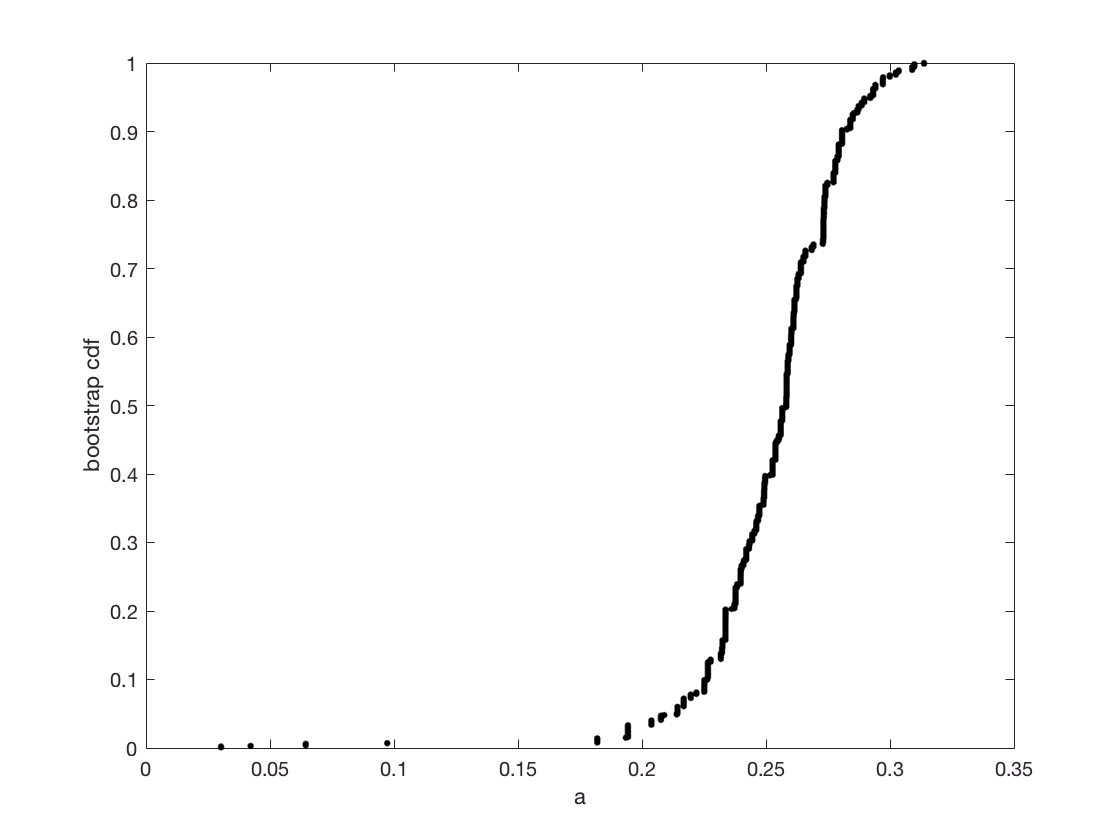

xBoot = sort(bootSamples);
yBoot = (1:length(bootSamples)) / length(bootSamples);
figure();
plot(xBoot, yBoot, 'k.', 'markersize', 20);
xlabel('a');
ylabel('bootstrap cdf');

Eyeballing it, it looks like our 95% confidence interval is $0.2 \le a \le 0.3$.  We can compute it.

lowHigh = prctile(bootSamples, [2.5, 97.5]);
disp(lowHigh);

    0.1943    0.2971



We can also compute the range of possible binding energy values.

   13.0937   13.5182



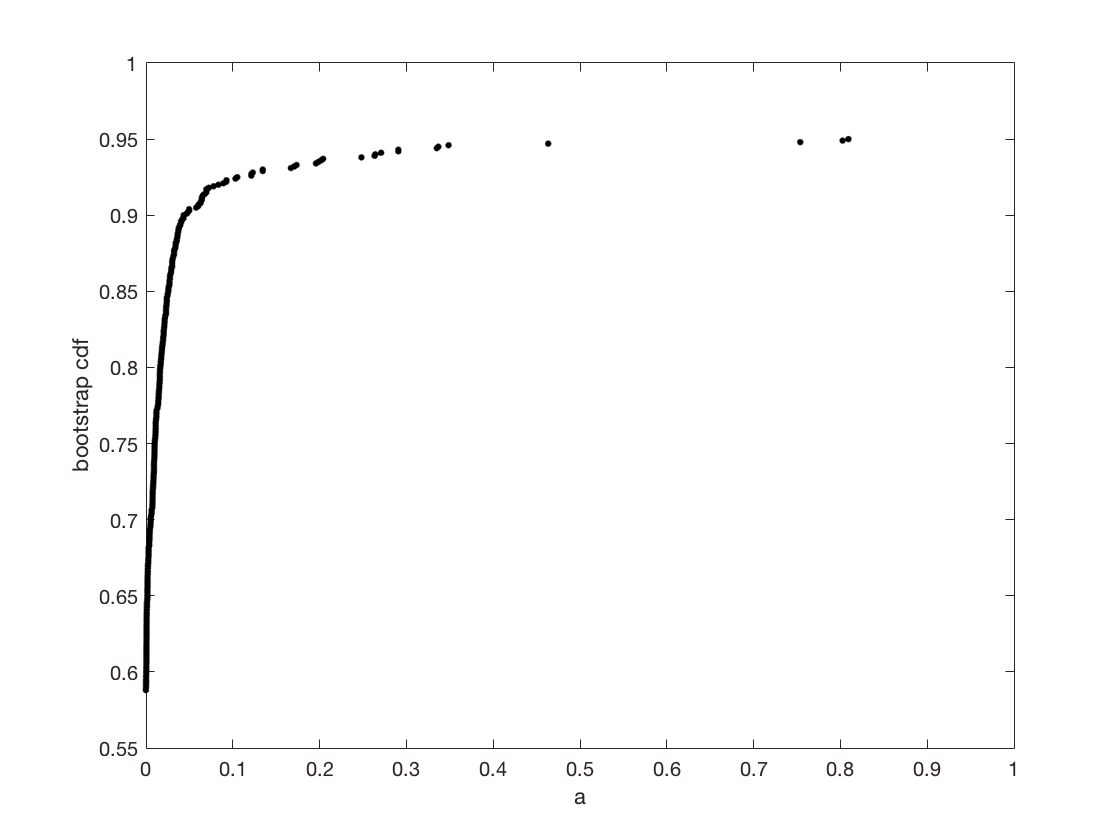

betaErd = -log(2 ./ lowHigh / 5e6);
disp(betaErd)

The logarithm damps out any wiggle room on the binding energy.